`8/1. Create the mesh`

`This procedure consists in six steps. The input is a T1 weighted MRI and the output is a volumetric mesh with five compartments, i.e., scalp, skull, cerebrospinal fluid (CSF), gray and white matter.`

Currently, the pipeline for computing the MEG forward problem solution has been tested on Ubuntu systems, where MATLAB should be started with the following command:

%s = settings;s.matlab.desktop.DisplayScaleFactor
%s.matlab.desktop.DisplayScaleFactor.PersonalValue = 2.0

%BLAS_VERSION=/usr/lib/libblas.so
%LD_PRELOAD=/usr/lib/x86_64-linux-gnu/libstdc++.so.6
%./matlab

`a. load the MRI`

addpath /home/ben/NIP_Projects/fieldtrip-20230503/
addpath /home/ben/NIP_Projects/fieldtrip-20230503/external/spm12
addpath /home/ben/NIP_Projects/fieldtrip-20230503/external/freesurfer
addpath /home/ben/NIP_Projects/fieldtrip-20230503/external/simbio
addpath /home/ben/NIP_Projects/fieldtrip-20230503/external/matplotlib
% ft_defaults

mri_orig = ft_read_mri(['Subject01/Subject01.mri']);

 In ft_estimate_units at line 51
 In ft_determine_units at line 117
 In ft_read_mri at line 809



Visualize the MRI

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
flipped the volume to make it consistent with the axes of the coordinate system
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1878
 In ft_sourceplot at line 1125

Press "h" to show this help.
Press "1", "2", or "3" to switch to the corresponding subplot.
Use the arrow keys to navigate in the current axis.
Click left mouse button to reposition the cursor.
Click and hold right mouse button to update the position while moving the mouse.
the call to "ft_sourceplot" took 3 seconds and required the additional allocation of an estimated 640 MB


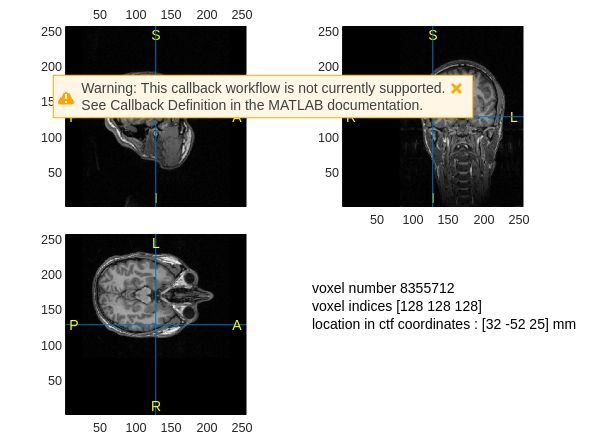

cfg = [];
ft_sourceplot(cfg,mri_orig);

b. realign the MRI

In this step we will interactively align the MRI to the CTF space. We will be asked to identify the three CTF landmarks (nasion, NAS; right pre-auricular point, RPA; left pre-auricular point, LPA) in the MRI.

cfg           = [];
cfg.method    = 'interactive';
cfg.coordsys  = 'ctf';
mri_realigned = ft_volumerealign(cfg, mri_orig);

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
flipped the volume to make it consistent with the axes of the coordinate system
0. Press "h" to show this help
1. To change the slice viewed in one plane, either:
   a. click (left mouse) in the image on a different plane. Eg, to view a more
      superior slice in the horizontal plane, click on a superior position in the
      coronal plane, or
   b. use the arrow keys to increase or decrease the slice numb

 In ft_volumerealign at line 1049

the call to "ft_volumerealign" took 4 seconds and required the additional allocation of an estimated 290 MB


We can visualize the realigned MRI

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1878
 In ft_sourceplot at line 1125

Press "h" to show this help.
Press "1", "2", or "3" to switch to the corresponding subplot.
Use the arrow keys to navigate in the current axis.
Click left mouse button to reposition the cursor.
Click and hold right mouse button to update the position while moving the mouse.
the call to "ft_sourceplot" took 1 seconds and required the additional allocation of an estimated 180 MB


cfg = [];
ft_sourceplot(cfg, mri_realigned);

c. reslice the MRI

cfg = [];
mri_resliced = ft_volumereslice(cfg, mri_realigned);

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
reslicing from [256 256 256] to [256 256 256]
the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.250000 mm
voxel size along 2nd dimension (j) : 1.250000 mm
voxel size along 3rd dimension (k) : 1.250000 mm
volume per voxel                   : 1.953125 mm^3
selecting subvolume of 90.4%
reslicing and interpolating anatomy
ininterpolating 100.0
the call to "ft_sourceinterpolate" took 5 seconds and required the additional allocation of an estimated 139

We can visualize the resliced MRI

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1878
 In ft_sourceplot at line 1125

Press "h" to show this help.
Press "1", "2", or "3" to switch to the corresponding subplot.
Use the arrow keys to navigate in the current axis.
Click left mouse button to reposition the cursor.
Click and hold right mouse button to update the position while moving the mouse.
the call to "ft_sourceplot" took 1 seconds and required the additional allocation of an estimated 1184 MB


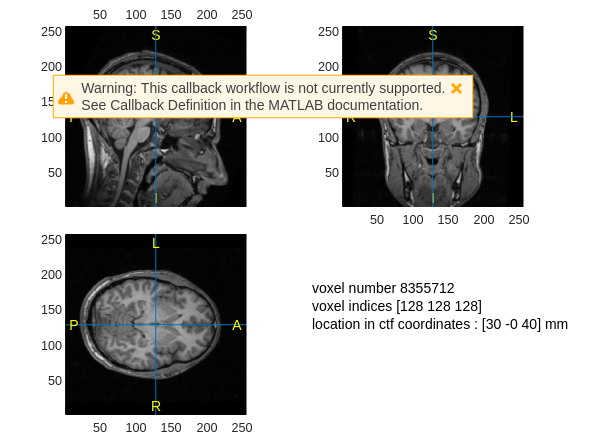

cfg = [];
ft_sourceplot(cfg, mri_resliced);

d. create surface meshes

For visualization purposes, we produce surface meshes for three compartments: scalp, skull and brain. In order to do that, we first have to segment the MRI into the three compartments.

cfg = [];
cfg.output = {'scalp', 'skull', 'brain'};
mri_segmented_3_compartment = ft_volumesegment(cfg, mri_resliced);

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
using 'OldNorm' normalisation
the coordinate system appears to be 'mni152'
Smoothing by 0 & 8mm..
Coarse Affine Registration..


Fine Affine Registration..
performing the segmentation on the specified volume, using the old-style segmentation

SPM12: spm_preproc (v4916)                         13:34:11 - 06/06/2023
Completed                               :          13:35:32 - 06/06/2023
creating scalpmask ... using the anatomy field for segmentation
smoothing anatomy with a 5-voxel FWHM kernel
thresholding anatomy at a relative threshold of 0.100
creating brainmask ... using the sum of gray, white and csf tpms
smoothing brainmask with a 5-voxel FWHM kernel
thresholding brainmask at a relative threshold of 0.500
creating skullmask ... using the brainmask
the call to "ft_volumesegment" took 121 seconds and required the additional allocation of an estimated 858 MB


Visualize the segmentation

seg_i = ft_datatype_segmentation(mri_segmented_3_compartment, 'segmentationstyle', 'indexed');

cfg              = [];
%cfg.funparameter = 'seg';
cfg.funparameter = 'seg';
cfg.funcolormap  = gray(4); % distinct color per tissue
cfg.location     = 'center';
cfg.atlas        = seg_i;
%ft_sourceplot(cfg, seg_i);

Once the segmentation is completed, the three surface meshes can be computed.

cfg  =[];
cfg.tissue      = {'scalp', 'skull', 'brain'};
cfg.numvertices = [3000 2000 1000];
mesh_surf       = ft_prepare_mesh(cfg,mri_segmented_3_compartment);

triangulating the boundary of compartment 1 (scalp) with 3000 vertices
triangulating the boundary of compartment 2 (skull) with 2000 vertices
triangulating the boundary of compartment 3 (brain) with 1000 vertices
the call to "ft_prepare_mesh" took 9 seconds and required the additional allocation of an estimated 432 MB


We can save the mesh obtained

save mesh_surf mesh_surf

e. segment the MRI

cfg                         = [];
cfg.output                  = {'scalp', 'skull', 'csf', 'gray', 'white'};
cfg.brainsmooth             = 2;
cfg.skullsmooth             = 2;
cfg.scalpsmooth             = 2;
mri_segmented_5_compartment = ft_volumesegment(cfg, mri_resliced);

the input is volume data with dimensions [256 256 256]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
using 'OldNorm' normalisation
the coordinate system appears to be 'mni152'
Smoothing by 0 & 8mm..
Coarse Affine Registration..
Fine Affine Registration..
performing the segmentation on the specified volume, using the old-style segmentation

SPM12: spm_preproc (v4916)                         13:36:20 - 06/06/2023
Completed                               :          13:37:38 - 06/06/2023
creating scalpmask ... using the anatomy field for segmentation
smoothing anatomy with a 2-voxel FWHM kernel
thresholding anatomy at a relative threshold of 0.100
creating brainmask ... using the sum of gray, white and csf tpms
smoothing brainmask with a 2-voxel FWHM kernel
thresholding

Visualize the segmentation result

seg_i = ft_datatype_segmentation(mri_segmented_5_compartment, 'segmentationstyle', 'indexed');

 In fixsegmentation at line 68
 In ft_datatype_segmentation at line 170




seg_i = ft_datatype_segmentation(mri_segmented_5_compartment, 'segmentationstyle', 'indexed');

 In fixsegmentation at line 68
 In ft_datatype_segmentation at line 170




cfg              = [];
cfg.funparameter = 'seg';
cfg.funcolormap  = gray(6); % distinct color per tissue (air is included)
cfg.location     = 'center';
cfg.atlas        = seg_i;    % the segmentation can also be used as atlas
%ft_sourceplot(cfg, seg_i);

f. create the mesh

cfg            = [];
cfg.shift      = 0.3;
cfg.method     = 'hexahedral';
cfg.resolution = 2; % this is in mm
cfg.tissue     = {'scalp', 'skull', 'csf', 'gray', 'white'};
mesh_fem       = ft_prepare_mesh(cfg,mri_segmented_5_compartment);

 In fixsegmentation at line 68
 In ft_datatype_segmentation at line 170
 In ft_checkdata at line 287
 In prepare_mesh_hexahedral at line 18
 In ft_prepare_mesh at line 169



 In ft_checkconfig at line 204
 In prepare_mesh_hexahedral at line 28
 In ft_prepare_mesh at line 169

using the field "tissue" with the segmented tissue types csf, gray, scalp, skull and white
Created elements...
Created nodes...
Applying shift 0.300000
the call to "ft_prepare_mesh" took 49 seconds and required the additional allocation of an estimated 306 MB


For this script we downsample the mesh to 2mm resolution, in order to reduce the computation time of the following steps.

## EEG forward solution computation

Once the volumetric mesh has been created, the forward solution can be computed. In the following, steps 2-5 are described for EEG.

## 2(EEG). Create the headmodel

cfg               = [];
cfg.method        = 'simbio';
cfg.conductivity  = [0.43 0.01 1.79 0.33 14];
cfg.tissuelabel   = {'scalp', 'skull', 'csf', 'gray', 'white'};
headmodel_fem_eeg = ft_prepare_headmodel(cfg, mesh_fem);

the call to "ft_prepare_headmodel" took 133 seconds and required the additional allocation of an estimated 922 MB


Visualize the headmodel and the electrodes (it might take time and memory)

% scalp: 1, skull: 2, csf: 3, gray: 4, wm: 5
ts = 1;
figure
mesh2 =[];
mesh2.hex = headmodel_fem_eeg.hex(headmodel_fem_eeg.tissue==ts,:); %mesh2.hex(1:size(mesh2.hex),:);
mesh2.pos =  headmodel_fem_eeg.pos;
mesh2.tissue =  headmodel_fem_eeg.tissue(headmodel_fem_eeg.tissue==ts,:); %mesh.tissue(1:size(mesh2.hex),:);

%mesh_ed = mesh2edge(mesh2);
%patch('Faces',mesh_ed.poly,...
%  'Vertices',mesh_ed.pos,...
%  'FaceAlpha',.5,...
%  'LineStyle', 'none',...
%  'FaceColor',[1 1 1],...
%  'FaceLighting', 'gouraud');

%xlabel('coronal');
%ylabel('sagital');
%zlabel('axial')
%camlight;
%axis on;

%ft_plot_sens(elec, 'style', '*g');

## 3(EEG). Create the sourcemodel

In this phase, source locations are selected within the gray matter compartment. During this tutorial we recommend to create a rather coarse grid (cfg.resolution = 5;), in order to be able to compute the forward solution in the time available in this course.

cfg                 = [];
cfg.resolution = 5; %in mm
cfg.headmodel       = headmodel_fem_eeg;
cfg.inwardshift     = 1; %shifts dipoles away from surfaces
%sourcemodel         = ft_prepare_sourcemodel(cfg, headmodel_fem_eeg);
sourcemodel         = ft_prepare_sourcemodel(cfg);

creating sourcemodel based on automatic 3D grid with specified resolution
creating 3D grid with 5 mm resolution
initial 3D grid dimensions are [47 38 51]
pruning headmodel volume elements from 4113803 to 775450 (19%)
pruning dipole positions from 91086 to 25515 (28%)
6055 dipoles inside, 85031 dipoles outside brain
making tight grid
6055 dipoles inside, 17813 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 7 seconds and required the additional allocation of an estimated 1340 MB


We can visualize the sources and the scalp surface mes

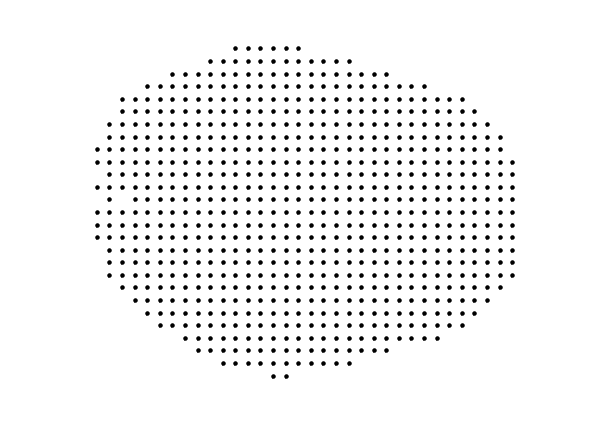

reducing triangles to 0 lines
this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


figure, ft_plot_mesh(sourcemodel.pos(sourcemodel.inside,:))
hold on, ft_plot_mesh(mesh_surf(1), 'surfaceonly', 'yes', 'vertexcolor', 'none', 'facecolor',...
           'skin', 'facealpha',0.5, 'edgealpha',0.1)

## 4(EEG). Handle the sensors

In case the electrodes are not aligned to the MRI (i.e., CTF space), we can use the interactive function as follows

% interactively coregister the electrodes to the FEM head model
% this is a visual check and refinement step
cfg = [];
cfg.method    = 'interactive';
elec = ft_read_sens('template/standard_1020.elc');
cfg.elec      = elec;

cfg           = [];
cfg.method    = 'interactive';
cfg.elec      = elec;
cfg.headshape = mesh_surf(1);
elec  = ft_electroderealign(cfg);

using electrodes specified in the configuration
Use the mouse to rotate the geometry, and click "redisplay" to update the light.
Close the figure when you are done.
the template coordinate system is unknown, selecting the viewpoint is not possible


orienting some EEG electrodes along the z-axis
Press "h" to show this help.
Press "q" or close the window when you are done.
Press "v" to update the light position.


the call to "ft_interactiverealign" took 85 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_electroderealign" took 85 seconds and required the additional allocation of an estimated 4 MB


## 5(EEG). Compute the leadfield

Please DO NOT run *ft_prepare_vol_sens* in this tutorial session! It will take too much time and memory. Load “headmodel_fem_eeg_tr”.

%% compute the transfer matrix
[headmodel_fem_eeg_tr, elec] = ft_prepare_vol_sens(headmodel_fem_eeg, elec);

reducing hexaheders to 203096 polygons
Find electrode positions...
Calculate transfer matrix...
Electrode 2 of 97
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5171e-09

Electrode 3 of 97
Scaling stiffness matrix...
Preconditioning...
Finding startvector...
Solving equation system...



%% compute the leadfield
cfg               = [];
cfg.grid          = sourcemodel;
cfg.headmodel     = headmodel_fem_eeg_tr;
cfg.elec          = elec;
cfg.reducerank    = 3;
leadfield_fem_eeg = ft_prepare_leadfield(cfg);